# Testing the Function SNHT_side_wall

## Simple Test Plane

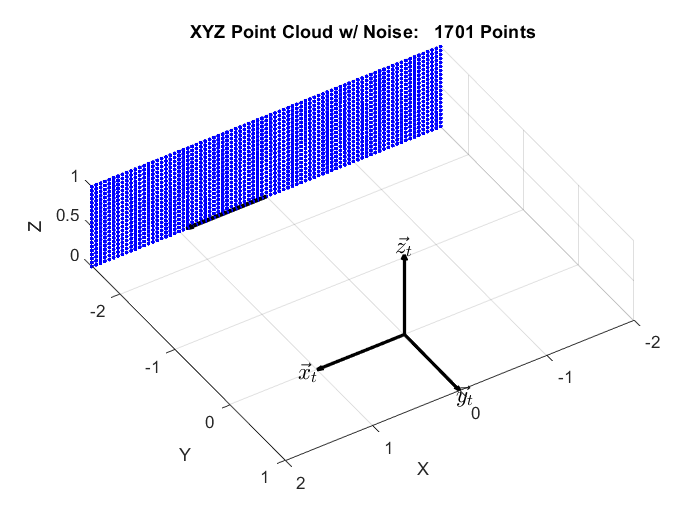

% Choose the Wall Heading in Degrees
psi   = 0 * pi/180;

% Fixed Parameters
C = rotate_z(psi) * rotate_z(pi/2) * rotate_y(pi/2);

% Additional Parameters to Adjust
org = [0, -2.5, 0];
dim = 1 * [-1 0; -2 2];
dx = 0.05; dy = 0.05;
sigmas = [0; 0; 0];
color = 'b';

% Generate XYZ Point Cloud using the Same Parameters
xyz = gen_plane(C, org, dim, dx, dy, sigmas);

% Plot Point Cloud and Axes
figure
hold on
plot_plane(C, org, dim, dx, dy, sigmas, color);
plot_frame(eye(3), zeros(3,1), 't', 'k');
quiver3(org(1), org(2), org(3), cos(psi), sin(psi), 0, 'k', 'LineWidth', 2.5)
title(['XYZ Point Cloud w/ Noise:   ', num2str(length(xyz)), ' Points'])
xlabel('X')
ylabel('Y')
zlabel('Z')
view([147.66 39.39])
axis equal
grid on
hold off

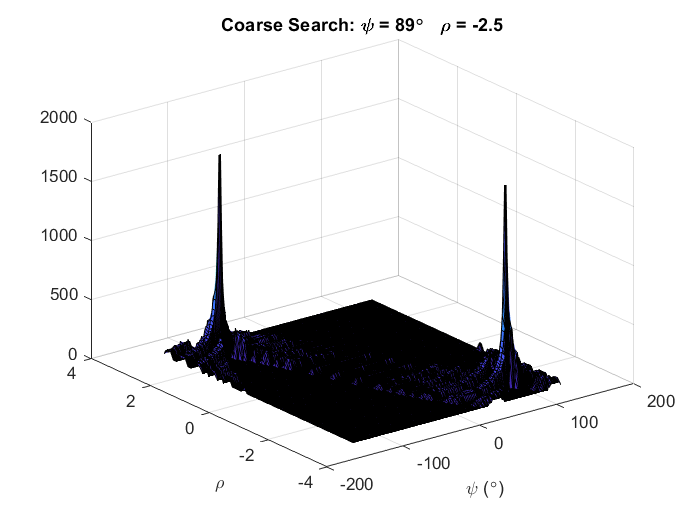

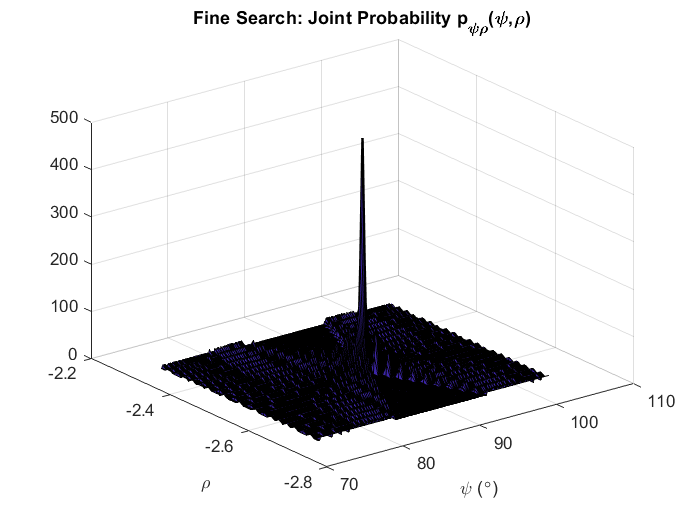

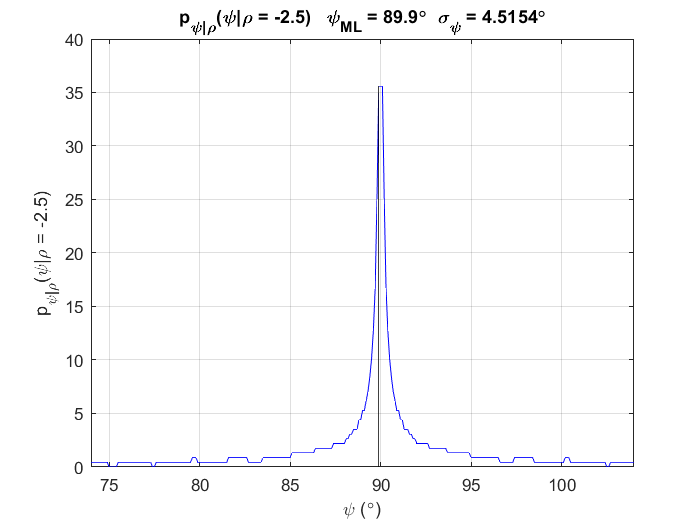

% Test the Algorithm
plot_flag = true;

% Call Function
tic
[psi_mode, psi_var] = SNHT_side_wall(xyz, plot_flag);

toc

Elapsed time is 1.207675 seconds.
